clear all
% sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2023_01_18_11_20_02_Jonas_70mm\download\';
% 
% sli_files_unk = dir([sli_file_path '*.unk']);
% sli_files_unc = dir([sli_file_path '*.unc']);
% for i=1:length(sli_files_unk)
%     [h,sli(i,:),m] = readAscImage([sli_file_path sli_files_unk(i).name]);  
% end
% 
% sli_file_path2 = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\2022_11_23_15_10_06\download\';
% 
% sli_files_unk2 = dir([sli_file_path2 '*.unk']);
% sli_files_unc2 = dir([sli_file_path2 '*.unc']);
% for i=1:length(sli_files_unk2)
%     [~,sli(i + length(sli_files_unk),:),~] = readAscImage([sli_file_path2 sli_files_unk2(i).name]);  
% end

sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_19_11_14_14_24_best_Jonas_20230118_60mm\download\';
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_15_53_40_24_best_Jonas_20230118_65mm\download\';
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_11_20_02_24_best_Jonas_20230118_70mm\download\';
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_14_36_33_24_best_Jonas_20230118_75mm\download\';
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_14_47_38_24_best_Jonas_20230118_80mm\download\';

sli_files_unk = dir([sli_file_path '*.unk']);
sli_files_unc = dir([sli_file_path '*.unc']);
for i=1:length(sli_files_unk)
    [h,sli(i,:),m] = readAscImage([sli_file_path sli_files_unk(i).name]);  
end

[img, map, alphachannel] = imread('Mask_binary_transparent.png');
img = img(:, :, 1)./255;

% Rotate and translate to "sensor frame"
sliID_approved = [];
sliID_data_mask = [];
sliID_data_ill = [];
for i=1:size(sli,1)
    sli_data{i}.cen = sli(i).sliData.cen;
    %sli_data{i}.sliID = sli(i).sliData.sliID;
    sliID_data_ill = [sliID_data_ill; sli(i).sliData.sliID];
    for j = 1:size(sli(i).sliData.cen, 1)   
        index = floor(sli(i).sliData.cen(j, 1:2));
        if(img(index(2), index(1)))
            sliID_data_mask = [sliID_data_mask; sli(i).sliData.sliID(j)];
        end
    end
end
%unique(sliID_approved)
%counts_mask = histc(unique(sliID_approved), unique_sli_mask_ID)


[unique_sli_mask_ID, idx_sliID_mask] = unique(sliID_data_mask);
counts_mask = histc(sliID_data_mask, unique_sli_mask_ID)

counts_mask =     24
     1
    24
    24
    24
    24
    24
    24
    24
    23


%unique_sli_mask_ID(counts_mask < size(sli,1) - 1)


[unique_sliID_ill_ID, idx_sliID] = unique(sliID_data_ill);
counts_ill = histc(sliID_data_ill, unique_sliID_ill_ID)

counts_ill =     24
     4
    24
    24
    24
    24
    24
    24
    24
    23


%unique_sliID_approved(counts_ill < size(sli,1) - 1)

sliID_approved = intersect(unique_sli_mask_ID(counts_mask >= size(sli,1) - 1), unique_sliID_ill_ID(counts_ill >= size(sli,1) - 1))

sliID_approved =     19
    27
    29
    32
    34
    38
    40
    48
   148
   149


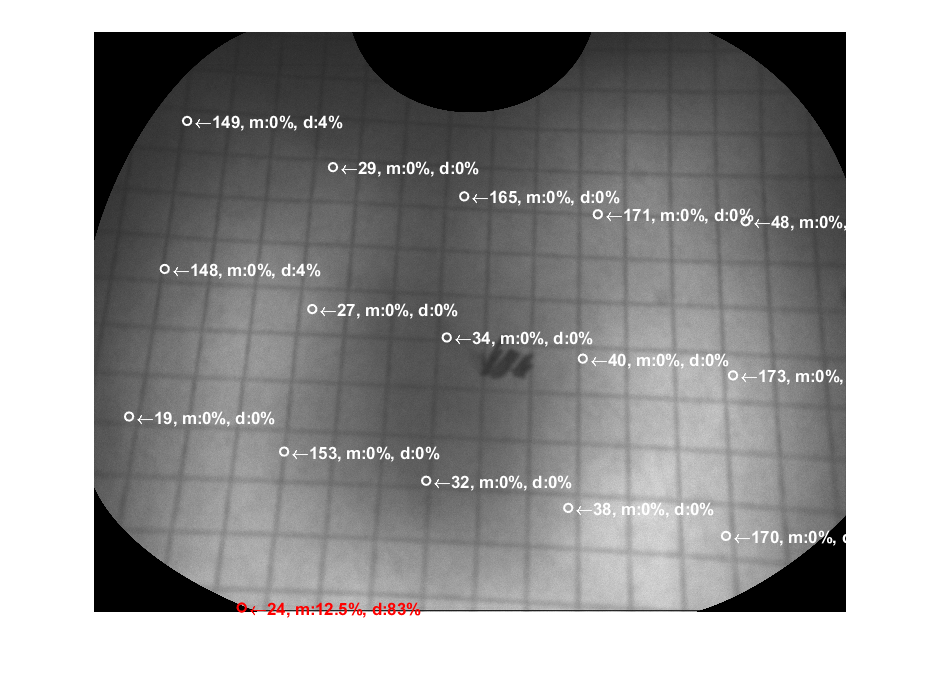


% for i = 1:size(sli, 1)
%     sli(i).sliHeader.Ncen
% end

k = 1;
%k = 7;
clf
figure(k)
[~,im_,~] = readAscImage([sli_file_path sli_files_unc(k).name]);
%[~,im_,~] = readAscImage('C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\raw_0644491135_000001C5_000004.unc');
%[~,im_,~] = readAscImage('C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\raw_0637735087_000F0206_000009.unc');
imshow(im_)
hold on
image(img, 'AlphaData', alphachannel);
%k = 53;
k = 20;
for m = 1:sli(k).sliHeader.Ncen
    cen = sli(k).sliData.cen(m, :);
    if (sli(k).sliData.sliID(m) ~= 255)
        if (ismember(sli(k).sliData.sliID(m), sliID_approved))
            plt = plot(cen(1), cen(2), 'wo'); 
            plt.MarkerSize = 5;
            plt.LineWidth = 1.25;
            txt = text(cen(1) + 7, cen(2), strcat('\leftarrow ', num2str(sli(k).sliData.sliID(m)), ...
                ', m: ', num2str(round((size(sli,1) - counts_mask(find(sli(k).sliData.sliID(m) == unique_sli_mask_ID)) - (size(sli,1) - counts_ill(find(sli(k).sliData.sliID(m) == unique_sliID_ill_ID))))/size(sli,1)*100, 2)), '%', ...
                ', d: ', num2str(round(round((size(sli,1) - counts_ill(find(sli(k).sliData.sliID(m) == unique_sliID_ill_ID)))/size(sli,1)*100, 2)), 4), '%' ));
            txt.Color = 'white';
            txt.FontSize = 10;
            txt.FontWeight = 'bold';
        else
            plt = plot(cen(1), cen(2), 'ro'); 
            plt.MarkerSize = 5;
            plt.LineWidth = 1.25;
            txt = text(cen(1) + 7, cen(2), strcat('\leftarrow ', num2str(sli(k).sliData.sliID(m)), ...
                ', m: ', num2str(round((size(sli,1) - counts_mask(find(sli(k).sliData.sliID(m) == unique_sli_mask_ID)) - (size(sli,1) - counts_ill(find(sli(k).sliData.sliID(m) == unique_sliID_ill_ID))))/size(sli,1)*100, 2)), '%', ...
                ', d: ', num2str(round(round((size(sli,1) - counts_ill(find(sli(k).sliData.sliID(m) == unique_sliID_ill_ID)))/size(sli,1)*100, 2)), 4), '%' ));
            txt.Color = 'red';
            txt.FontSize = 10;
            txt.FontWeight = 'bold';
        end
    end
end

% ID 149 should be expected to appear at 80 mm - 30 and 35 more likely to
% disappear
% ID 30 and 35 should be expected to appear at 60 mm - 149 and maybe 29 and
% 165 likely to disappear

% When we increase the distance, the SLI points migrate north
% When we decrease the distance, the SLI points migrate south
% When you tilt towards south, points in the top should reappear at greater
% angles because the distance to the points increases

    